# Continuous Battery Implementation

- continuous dynamics

- continuous degradation

- Load based degradation (amp hours)

### Load the UAV

load('uav.mat')

### Discharge the battery

% current
u = 60;
res = sim("continuous_battery.slx");

### The battery parameters persist after simulation

uav.battery.v = res.battery_state_params.v.Data(end);
uav.battery.z = res.battery_state_params.z.Data(end);

### Calculate battery age

- expressed on the scale 0.0 - 1.0, 1.0 = eol (as defined by the lifetime amp hours of usage available)

avg_current = abs(mean(res.u.Data));
time = res.time.Data(end)/3600;
amp_hours = avg_current * time;
uav.battery.amp_hours = uav.battery.amp_hours + amp_hours;
uav.battery.amp_hours

ans = 21.0183

uav.battery.age = uav.battery.amp_hours / uav.battery.lifetime_amp_hrs;
uav.battery.age

ans = 0.0016

### Update degradation parameters

uav.battery.Q = polyval(uav.battery.q_coef, uav.battery.amp_hours);
uav.battery.Q

ans = 21.7785

uav.battery.R0 = polyval(uav.battery.r_coef, uav.battery.amp_hours);
uav.battery.R0

ans = 0.0011

### Plot output voltage

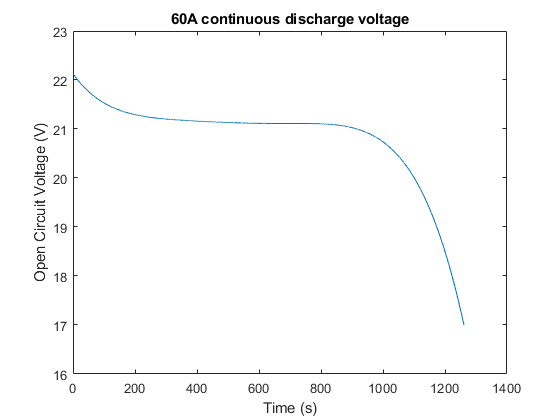

f1 = figure(1); clf;
plot(res.battery_state_params.v.Time, res.battery_state_params.v.Data);
title("60A continuous discharge voltage");
xlabel("Time (s)");
ylabel("Open Circuit Voltage (V)")

### Plot state of charge

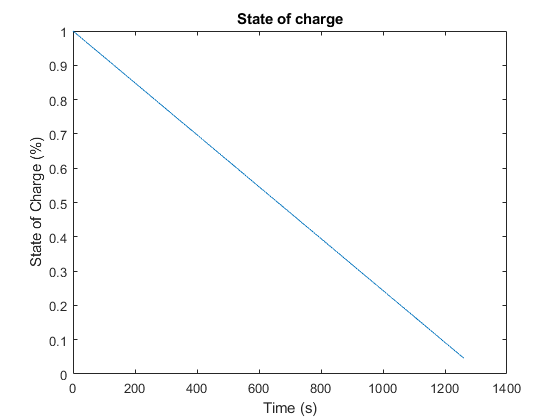

f2 = figure(2); clf;
plot(res.battery_state_params.z.Time, res.battery_state_params.z.Data);
title("State of charge");
xlabel("Time (s)");
ylabel("State of Charge (%)");

### Charge the battery

% standard charging practice is 1C
u = -uav.battery.Q;
res = sim("continuous_battery.slx");

### The battery parameters persist after simulation

uav.battery.v = res.battery_state_params.v.Data(end);
uav.battery.z = res.battery_state_params.z.Data(end);

### Calculate battery age

- expressed on the scale 0.0 - 1.0, 1.0 = eol (as defined by the lifetime amp hours of usage available)

avg_current = abs(mean(res.u.Data));
time = res.time.Data(end)/3600;
amp_hours = avg_current * time;
uav.battery.amp_hours = uav.battery.amp_hours + amp_hours;
uav.battery.amp_hours

ans = 41.8252

uav.battery.age = uav.battery.amp_hours / uav.battery.lifetime_amp_hrs;
uav.battery.age

ans = 0.0031

### Update degradation parameters

uav.battery.Q = polyval(uav.battery.q_coef, uav.battery.amp_hours);
uav.battery.Q

ans = 21.7789

uav.battery.R0 = polyval(uav.battery.r_coef, uav.battery.amp_hours);
uav.battery.R0

ans = 0.0011

### Plot output voltage

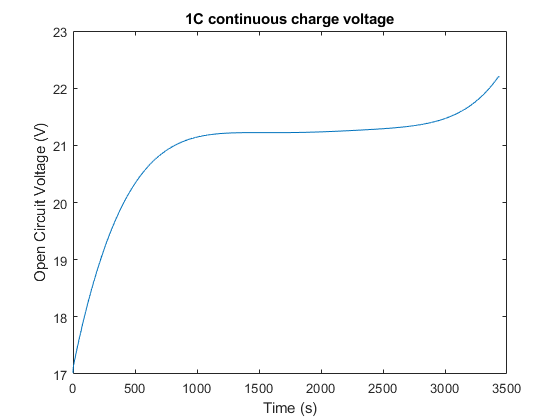

f3 = figure(3); clf;
plot(res.battery_state_params.v.Time, res.battery_state_params.v.Data);
title("1C continuous charge voltage");
xlabel("Time (s)");
ylabel("Open Circuit Voltage (V)")

### Plot state of charge

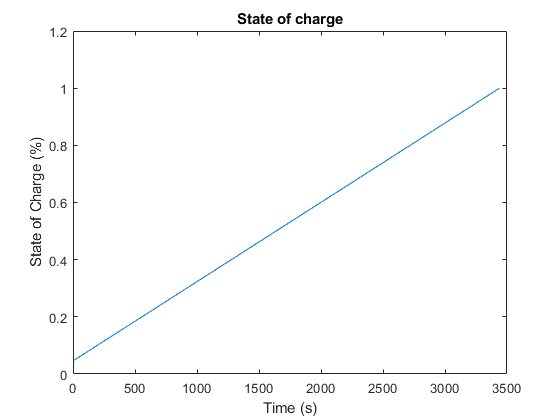

f4 = figure(4); clf;
plot(res.battery_state_params.z.Time, res.battery_state_params.z.Data);
title("State of charge");
xlabel("Time (s)");
ylabel("State of Charge (%)")